#               Computational Electromagnetics 

##                                             Hw3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/18      

## Q-3.25:   

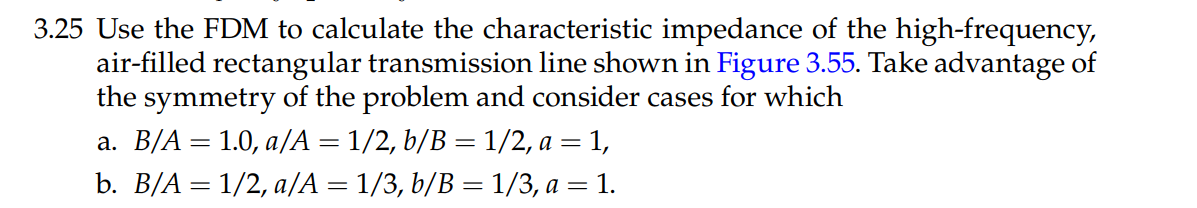

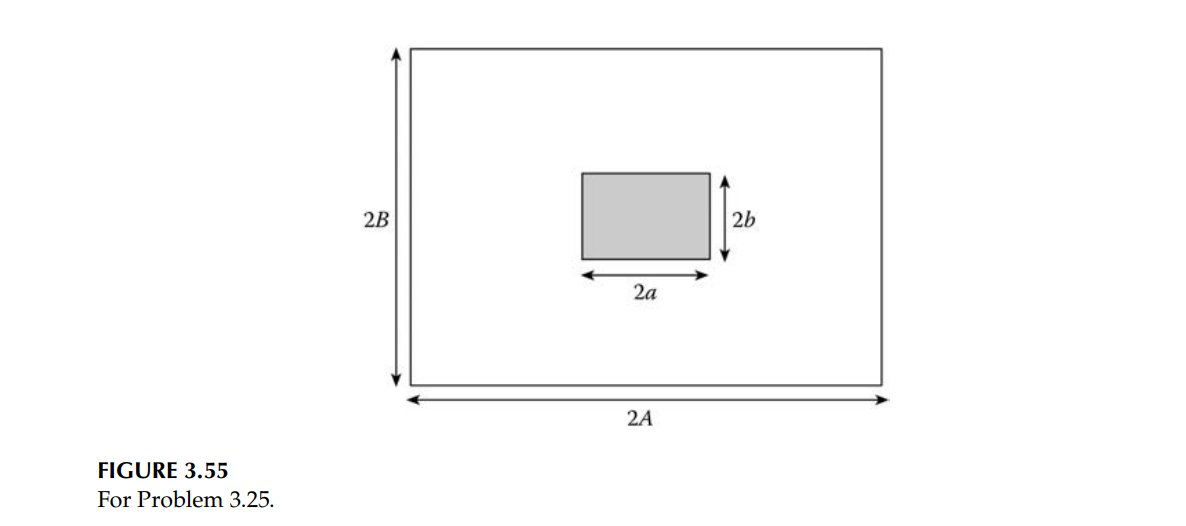

To take advantage of the symmetry we can consider a quadrature and then extend the result for the whole geometry!  ==> what we consider is:

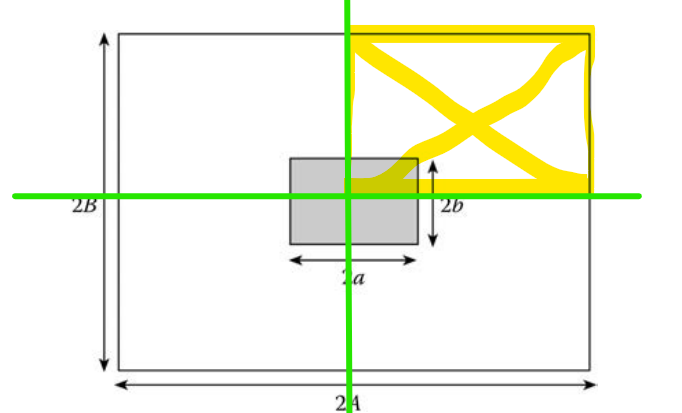

The Conductor at the core will be:                        0<x<a ;   0<y<b;   

The area is filled with air;

We have to consider symmetry condition along X-Axis and Y-Axis! --> 

Not Important due to the fact that the conductor potential stays zero within but on the surface!

The Tranmission line is filled with air! --> eps0

We can solve this for Tm or TE modes!  

The Equation to satisfy is:

For TM --> Hz=0 ; Ez != 0 ;  PHI = EZ --> Boundary Condition becomes: PHI = 0; at PEC --> Dirichlet Condition

For TE --> Hz != 0 ; Ez = 0 ;  PHI = HZ --> Boundary Condition becomes: dPHI/dn = 0; at PEC ---> Neumann Condition

If we have to solve an eigne value problem we have to form the** Matrix A** and initialize **Maxtrix PHI!**

The Correct FD formula for this problem is:

clear; clc; close all;
% SOlving for TM modes:
% Case 1:

eps0 = 8.854178128e-12 ; % Vacuum Permitivity   [F.m-1]

a=1;
A = 2*a;
B = A;
b = 1/2*B;

% h=1.0; 
% w = h; 
% t=0.01;  
% A  = a; B=b/2; D=h; W=w/2;


H = 0.01; 
NT = 1000;



ER = 1 ;
EO = 8.81e-12;
U = 3.0e+8;

NX  = A/H;
NY  = B/H;

ND  = b/H;
NW  = a/H;

VD  = 1.0;



## Iterative Method

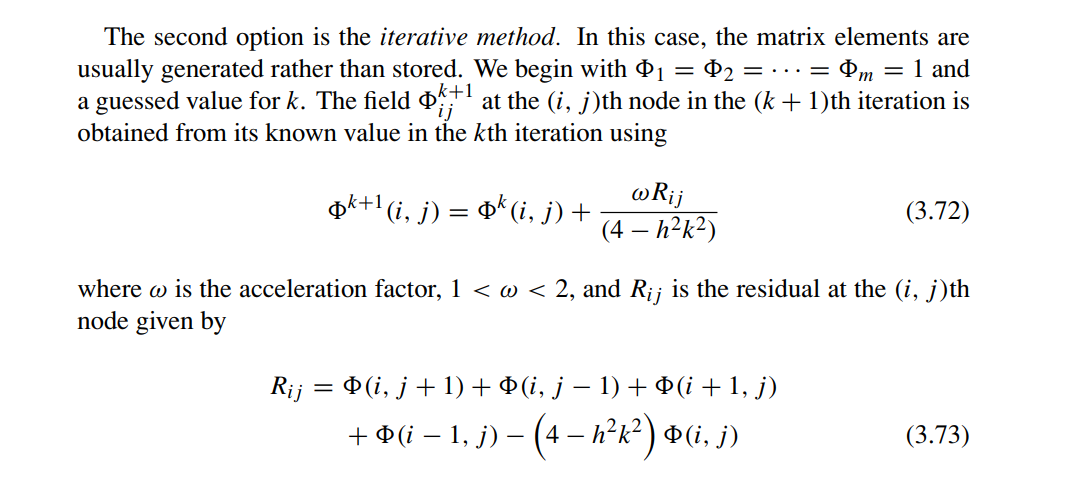

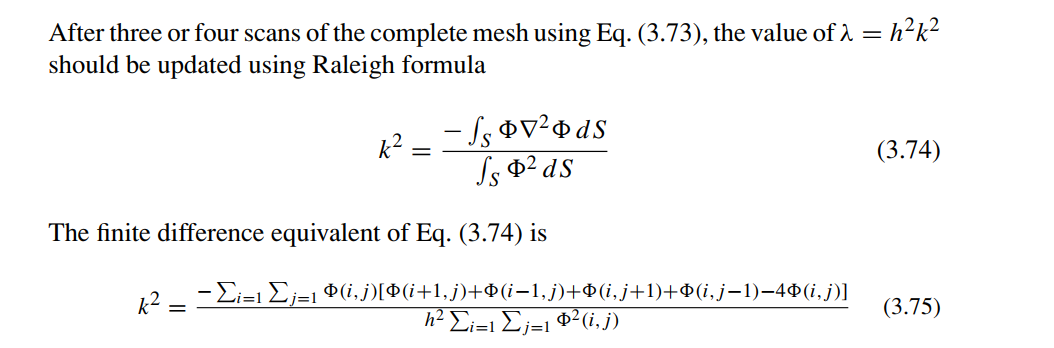

Iters=1e2;

PHI = zeros(NX,NY);R = PHI;  K = zeros(Iters,1);

w= 1.5; % shall be between 1,2
flag=0; thresh = 1e-2;

% Air Filled:
for k=1:Iters
    if (flag)
        return
    end

    if (k>4)
        % Update k using Raleigh Formula:
        SUM1= 0;
        SUM2=0;
        for i=1:NX-1
            for j=1:NY-1
                if (i==1)
                    if(j==1)
                     SUM1 = SUM1 + PHI(i,j)* (PHI(i+1,j) + 0 +PHI(i,j+1)+0- 4*PHI(i,j)  );
                    else
                     SUM1 = SUM1 + PHI(i,j)* (PHI(i+1,j) + 0 +PHI(i,j+1)+PHI(i,j-1)- 4*PHI(i,j)  );
                    end

                elseif (j==1)
                    if(i==1)
                        SUM1 = SUM1 + PHI(i,j)* (PHI(i+1,j)+0+PHI(i,j+1)+0- 4*PHI(i,j)  );

                    else
                        SUM1 = SUM1 + PHI(i,j)* (PHI(i+1,j)+PHI(i-1,j)+PHI(i,j+1)+0- 4*PHI(i,j)  );

                    end
                    
                else
                    SUM1 = SUM1 + PHI(i,j)* (PHI(i+1,j)+PHI(i-1,j)+PHI(i,j+1)+PHI(i,j-1)- 4*PHI(i,j)  );

                end

                SUM2 = SUM2 + H^2*PHI(i,j)^2;
            end
        end
        K(k)  =sqrt( -SUM1/SUM2);
        if(abs(K(k)-K(k-1)) < thresh )
            flag = 1; % SOLVED
        end

    else
        K(k) = k;
    end

    

    for i=1:NX
        for j=1:NY
            if((i<NW)& (j<ND))
                PHI(i,j) = 0;
            elseif ( (i<NW)& (j==ND) )
                PHI(i,j)  =VD;  % On the surface of PEC Ez = 0; for TM modes where we have PHI = Ez; , Hz=0;
            elseif ( (i==NW) & (j<ND) )
                PHI(i,j) =VD;
            elseif ( i==1 )
                PHI(i,j) =0;
            elseif (j==1)
                PHI(i,j) =0;
            elseif (j==NY)
                PHI(i,j) =0;
            elseif (i==NX)
                PHI(i,j) =0;
            else
                R(i,j)  = PHI(i,j+1) +  PHI(i,j-1) + PHI(i+1,j) + PHI(i-1,j) - (4 - H^2*K(k)^2)*PHI(i,j)  ;
                PHI(i,j) =  PHI(i,j) + w*R(i,j)/(4-H^2*K(k)^2);

            end

       
        end
    end
    

end

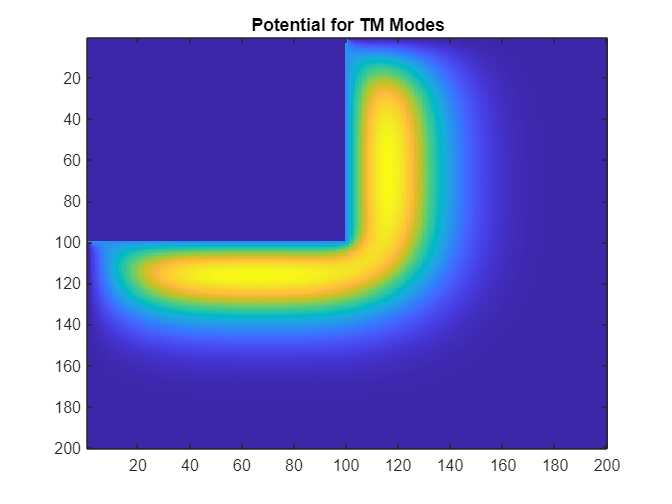

figure()
imagesc(PHI)
title("Potential for TM Modes")

## QUA-SI TEM Solution

clear;

a=1;
A = 2*a;
B = A;
b = 1/2*B;

H = 0.01; 
NT = 1000;


ER = 1 ;
EO = 8.81e-12;
U = 3.0e+8;

NX  = A/H;
NY  = B/H;
% ND  = D/H;
% NW  = W/H;
Na = a/H;
Nb = b/H ;

VD  = 1.0;

% Calculate charge with and without DIELECTRIC


E1 = EO;



% INITIALIZATION

    V = zeros(NX+2,NY+2);

% Set POTENTIAL ON INNER CONDUCTOR (FIXED NODES) EQUAL TO VD
    V(2:Na+1,Nb+2)  =VD; % Parallel to Y-Axis
    V(Na+2,2:Nb+1)  =VD; % Parallel to X-Axis

% CALCULATE POTENTIAL AT FREE NODES --> Laplace Equation --> a TEM
% structure

    for K=1:NT
        for I=0:NX-1
            for J=0:NY-1
                if( (J<=Nb)&(I<=Na)  ) % In The PEC
                    % do nothing
%                 elseif (J==Nb)
%                     % IMPOSE BOUNDARY Condition at the Interface
%                     V(I+2,J+2) = 0.25*( V(I+3,J+2) +  V(I+1,J+2)   )  + P1*V(I+2,J+3) + P2*V(I+2,J+1);
                elseif (I==0)
                    % IMPOSE Symmetry COndition Along with Y-AXIS
                    V(I+2,J+2) = ( 2*V(I+3,J+2) + V(I+2,J+3) + V(I+2,J+1)   )/4.0;
                elseif (J==0)
                    % IMPOSE Symmetry COndition Along with X-AXIS
                    V(I+2,J+2) = ( V(I+3,J+2) + V(I+1,J+2) + 2*V(I+2,J+3)   )/4.0;
                else 
                    V(I+2,J+2) = (  V(I+3,J+2) + V(I+1,J+2) + V(I+2,J+3) + V(I+2,J+1) )/4.0;
                end
            end
        end
        % ANimation of Calculation
%         figure(1);
%         imagesc(V);
%         colorbar;
%         title([num2str(K),'/' , num2str(NT) ])
%         drawnow


    end
    

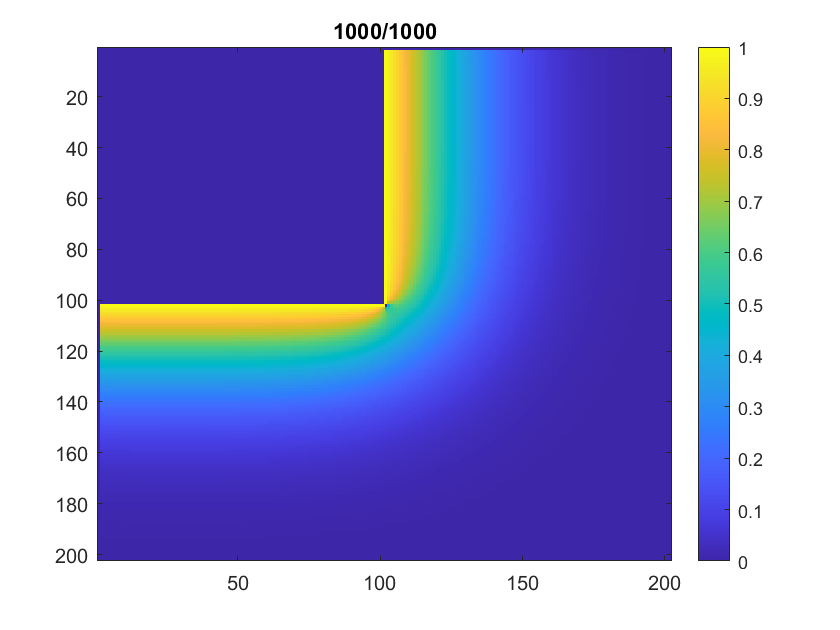

figure(1);
        imagesc(V);
        colorbar;
        title([num2str(K),'/' , num2str(NT) ])


% Now Calculate the TOTAL CHARGE ENCLOSED IN A Rectangular Path Surrounding the Inner CONDUCTOR:
    IOUT = round((NX+Na)/2) ;
    JOUT = round((NY+Nb)/2) ;
% SUM Potential on Inner and Outer LOOPS:

    SUM1 = E1* sum( V(3:IOUT+1 , JOUT+2)  )  + E1*V(2,JOUT+2)/2 + E1*V(IOUT+2,2)/2;
    for J=1:JOUT-1            
            SUM1 =SUM1 + E1*V(IOUT+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
    end

    %SUM1  = SUM1 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point
    IOUT = IOUT-1;
    JOUT = JOUT -1;

    SUM2 = E1* sum( V(3:IOUT+1 , JOUT+2)  )  + E1*V(2,JOUT+2)/2 + E1*V(IOUT+2,2)/2;
    for J=1:JOUT-1            
            SUM2 =SUM2 + E1*V(IOUT+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
    end
    SUM2  = SUM2 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point


%     SUM2  = E1* sum( V(3:Na+1 , Nb+2)  )  + E1*V(2,Nb+2)/2 + E1*V(Na+2,2)/2;
%     for J=1:Nb+2            
%             SUM2 =SUM2 + E1*V(Na+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
%     end
%     SUM2  = SUM2 + 2.0* E1* V(Na+2,Nb+2);  % Corner Point

    Q  = abs(SUM1 - SUM2 );

  % Calculate the Z0:
    C0 = 4.0*Q/VD ;  % *4  --> Due to Symmetry
    Z0 = 1.0/( U*C0 );  %  u = 1/sqrt(LC) ;--> L = 1/ (u2c) ,   Z0 = sqrt(L/C) --> Z0 = 1/(cu); 

    disp([H,NT]);

   1.0e+03 *

    0.0000    1.0000



    disp(Z0)

   58.5036



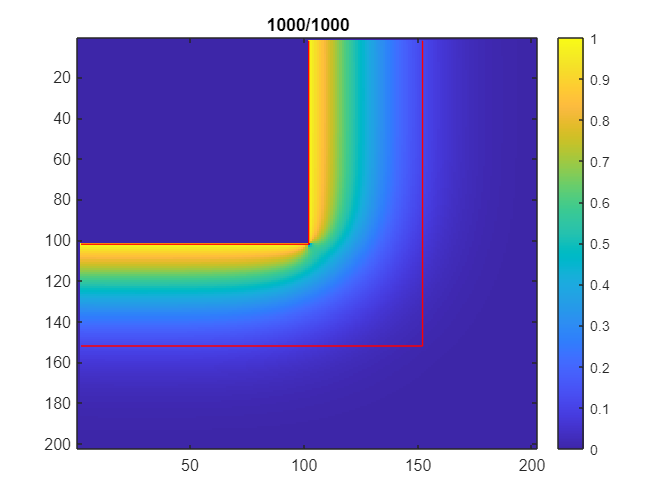

figure(2);
imagesc(V);
colorbar;
title([num2str(K),'/' , num2str(NT) ])
hold on
line([IOUT+2,IOUT+2], [2,JOUT+2], 'Color', 'r');
line([2,IOUT+2], [JOUT+2,JOUT+2], 'Color', 'r');

line([Na+2,Na+2], [2,Nb+2], 'Color', 'r');
line([2,Na+2], [Nb+2,Nb+2], 'Color', 'r');

Init.a=1; Init.A=2*Init.a ;    Init.B= Init.A ;    Init.b= 1/2 * Init.B ;   Init.ER =1 ; Init.animate=0;
Init.H= 1e-2;
Init.NT= 5e3 ;


Answer1 = FDM_Solver(Init);
Init.H= 1e-2;
Init.NT= 1e3 ;

Answer2 = FDM_Solver(Init);

Init.H= 1e-1;
Init.NT= 1e3 ;

Answer3 = FDM_Solver(Init);

Init.H= 1e-1;
Init.NT= 5e3 ;

Answer4 = FDM_Solver(Init);

Init.H= 1e-3;
Init.NT= 5e3 ;

Answer5 = FDM_Solver(Init);


Init.H= 1e-3;
Init.NT= 1e3 ;

Answer6 = FDM_Solver(Init);

Init.H= 1e-3;
Init.NT= 10e3 ;

Answer7 = FDM_Solver(Init);

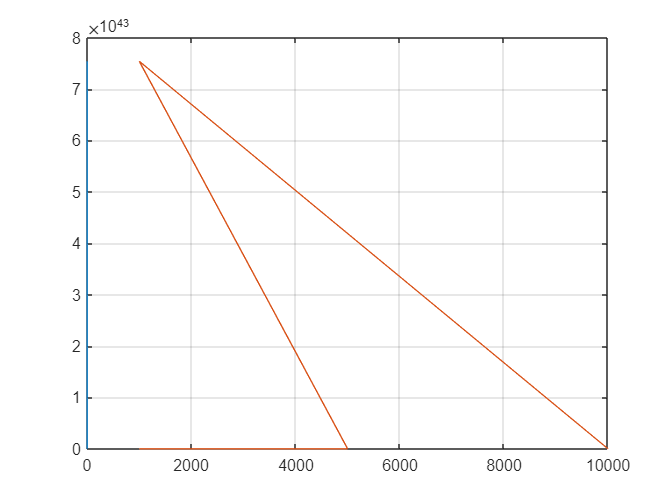

H_vec = [ 1e-1;1e-1;1e-2;1e-2;1e-3;1e-3;1e-3];
Z0_vec = [Answer1.Z0, Answer2.Z0,Answer3.Z0,Answer4.Z0,Answer5.Z0,Answer6.Z0,Answer7.Z0 ];
NT_vec = [ 1e3, 5e3 , 5e3 , 1e3 ,5e3 ,1e3 ,10e3 ];

figure()
plot(H_vec,Z0_vec);
hold on
plot(NT_vec,Z0_vec);
grid on

we can see that there is a an abnormal answer above! --> removing that answer!

Z0_answer6  =7.5398e+48   !!!!  

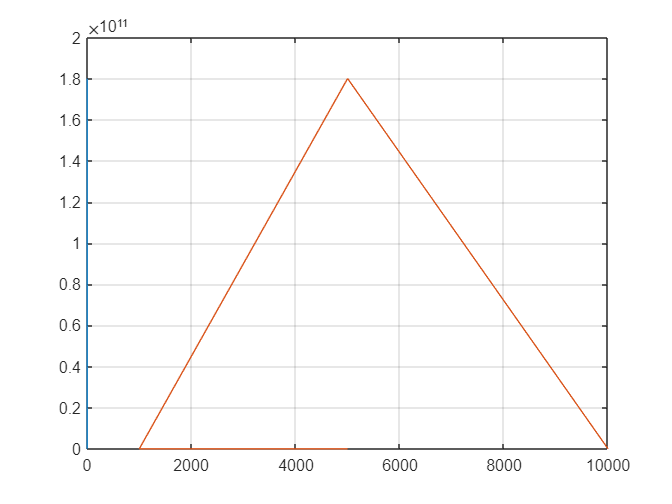




Z0_vec = Z0_vec(1,[1:5,7]);
H_vec = H_vec([1:5,7],1) ;
NT_vec  =  NT_vec(1,[1:5,7]) ;

figure()
plot(H_vec,Z0_vec);
hold on
plot(NT_vec,Z0_vec);
grid on

Again we have another abnormality! --> removing that one too!

H_vec = [ 1e-1;1e-1;1e-2;1e-2;1e-3;1e-3;1e-3];
Z0_vec = [Answer1.Z0, Answer2.Z0,Answer3.Z0,Answer4.Z0,Answer5.Z0,Answer6.Z0,Answer7.Z0 ];
NT_vec = [ 1e3, 5e3 , 5e3 , 1e3 ,5e3 ,1e3 ,10e3 ];

disp(Z0_vec(1,[1:4]));  

   73.9536  112.0905   69.5867   69.5867



disp(H_vec');

    0.1000    0.1000    0.0100    0.0100    0.0010    0.0010    0.0010



disp(NT_vec)

        1000        5000        5000        1000        5000        1000       10000



for smaller H -->0.001 we could not reach a certain point! -->

disp(Z0_vec(1,7)); % Answer 7 --> for 10e3 iterations , H = 0.001

   2.2974e+06



disp(Z0_vec(1,6)); % Answer 6 --> for 1e3 iterations , H = 0.001 --> shall be a bad answer

   7.5398e+43



disp(Z0_vec(1,5)); % Answer 5 --> for 5e3 iterations , H = 0.001 --> shall be a better answer than 6

   1.8011e+11



It is clear that with increase in Number of iterations the answer is getting closer to what it should be! Need more iterations for such H! -->

The Answer Converges for  H = 0.1 , 0.01.

Scenario 2:

Init.a=1; Init.A=3*Init.a ;    Init.B= 1/2* Init.A ;    Init.b= 1/3 * Init.B ;   Init.ER =1 ; Init.animate=0;

Init.H= 1e-1;
Init.NT= 1e3 ;
Answer1_2 = FDM_Solver(Init);


Init.H= 1e-1;
Init.NT= 5e3 ;
Answer2_2 = FDM_Solver(Init);

Init.H= 1e-1;
Init.NT= 10e3 ;
Answer3_2 = FDM_Solver(Init);

Init.H= 1e-2;
Init.NT= 1e3 ;
Answer4_2 = FDM_Solver(Init);

Init.H= 1e-2;
Init.NT= 5e3 ;
Answer5_2 = FDM_Solver(Init);

Init.H= 1e-2;
Init.NT= 10e3 ;
Answer6_2 = FDM_Solver(Init);



Init.H= 0.5e-2;
Init.NT= 1e3 ;
Answer7_2 = FDM_Solver(Init);


Init.H= 0.5e-2;
Init.NT= 5e3 ;
Answer8_2 = FDM_Solver(Init);

Init.H= 0.5e-2;
Init.NT= 10e3 ;
Answer9_2 = FDM_Solver(Init);

disp("Z0 = "+Answer1_2.Z0 + "with H = " +Answer1_2.H + " for NT = "+Answer1_2.NT )

Z0 = 72.4708with H = 0.1 for NT = 1000


disp("Z0 = "+Answer2_2.Z0 + "with H = " +Answer2_2.H + " for NT = "+Answer2_2.NT )

Z0 = 72.4708with H = 0.1 for NT = 5000


disp("Z0 = "+Answer3_2.Z0 + "with H = " +Answer3_2.H + " for NT = "+Answer3_2.NT )

Z0 = 72.4708with H = 0.1 for NT = 10000


disp("Z0 = "+Answer4_2.Z0 + "with H = " +Answer4_2.H + " for NT = "+Answer4_2.NT )

Z0 = 121.9418with H = 0.01 for NT = 1000


disp("Z0 = "+Answer5_2.Z0 + "with H = " +Answer5_2.H + " for NT = "+Answer5_2.NT )

Z0 = 80.5942with H = 0.01 for NT = 5000


disp("Z0 = "+Answer6_2.Z0 + "with H = " +Answer6_2.H + " for NT = "+Answer6_2.NT )

Z0 = 76.7403with H = 0.01 for NT = 10000


disp("Z0 = "+Answer7_2.Z0 + "with H = " +Answer7_2.H + " for NT = "+Answer7_2.NT )

Z0 = 2163.2999with H = 0.005 for NT = 1000


disp("Z0 = "+Answer8_2.Z0 + "with H = " +Answer8_2.H + " for NT = "+Answer8_2.NT )

Z0 = 107.7186with H = 0.005 for NT = 5000


disp("Z0 = "+Answer9_2.Z0 + "with H = " +Answer9_2.H + " for NT = "+Answer9_2.NT )

Z0 = 87.5667with H = 0.005 for NT = 10000


The Convergence is obvious and needs no discussion!  --> The  Exact solution is 50 ohm --> Convergence is to [72-87] interval !

function  OBJ = FDM_Solver(Init)


a = Init.a;
A  =Init.A;
B = Init.B;
b = Init.b;

H = Init.H;
NT = Init.NT;

OBJ.H = H;
OBJ.NT = NT;

ER = Init.ER;
EO = 8.81e-12; % Constant
U = 3.0e+8; % COnstant

OBJ.NX  = A/H;
OBJ.NY  = B/H;
OBJ.Na = a/H;
OBJ.Nb = b/H ;

OBJ.VD  = 1.0;  % a favorable Value

E1 = EO; % The Area is filled with Air!
% INITIALIZATION

    OBJ.V = zeros(OBJ.NX+2,OBJ.NY+2);

% Set POTENTIAL ON INNER CONDUCTOR (FIXED NODES) EQUAL TO VD
    OBJ.V(2:OBJ.Na+1,OBJ.Nb+2)  = OBJ.VD; % Parallel to Y-Axis
    OBJ.V(OBJ.Na+2,2:OBJ.Nb+1)  = OBJ.VD; % Parallel to X-Axis

% CALCULATE POTENTIAL AT FREE NODES --> Laplace Equation --> a TEM
% structure

    for K=1:NT
        for I=0:OBJ.NX-1
            for J=0:OBJ.NY-1
                if( (J<=OBJ.Nb)&(I< OBJ.Na)  ) % In The PEC
                    % do nothing
%                 elseif (J==Nb)
%                     % IMPOSE BOUNDARY Condition at the Interface
%                     V(I+2,J+2) = 0.25*( V(I+3,J+2) +  V(I+1,J+2)   )  + P1*V(I+2,J+3) + P2*V(I+2,J+1);
                elseif (I==0)
                    % IMPOSE Symmetry COndition Along with Y-AXIS
                    OBJ.V(I+2,J+2) = ( 2*OBJ.V(I+3,J+2) + OBJ.V(I+2,J+3) + OBJ.V(I+2,J+1)   )/4.0;
                elseif (J==0)
                    % IMPOSE Symmetry COndition Along with X-AXIS
                    OBJ.V(I+2,J+2) = ( OBJ.V(I+3,J+2) + OBJ.V(I+1,J+2) + 2*OBJ.V(I+2,J+3)   )/4.0;
                else 
                    OBJ.V(I+2,J+2) = (  OBJ.V(I+3,J+2) + OBJ.V(I+1,J+2) + OBJ.V(I+2,J+3) + OBJ.V(I+2,J+1) )/4.0;
                end
            end
        end
        % ANimation of Calculation
        if(Init.animate)
        figure(1);
        imagesc(OBJ.V);
        colorbar;
        title([num2str(K),'/' , num2str(NT) ])
        drawnow
        end
    end

    % Now Calculate the TOTAL CHARGE ENCLOSED IN A Rectangular Path Surrounding the Inner CONDUCTOR:
    OBJ.IOUT = round((OBJ.NX+OBJ.Na)/2) ;
    OBJ.JOUT = round((OBJ.NY+OBJ.Nb)/2) ;
    % SUM Potential on Inner and Outer LOOPS:
    OBJ.SUM1 =0;
    OBJ.SUM1 = E1* sum( OBJ.V(3:OBJ.IOUT+1 , OBJ.JOUT+2)  )  + E1*OBJ.V(2,OBJ.JOUT+2)/2 + E1*OBJ.V(OBJ.IOUT+2,2)/2;
    for J=1:OBJ.JOUT-1            
            OBJ.SUM1 = OBJ.SUM1 + E1*OBJ.V(OBJ.IOUT+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
    end

    %SUM1  = SUM1 + 2.0* E1* V(IOUT+2,JOUT+2);  % Corner Point
    OBJ.IOUT = OBJ.IOUT-1;
    OBJ.JOUT = OBJ.JOUT -1;

    OBJ.SUM2 = E1* sum( OBJ.V(3:OBJ.IOUT+1 , OBJ.JOUT+2)  )  + E1*OBJ.V(2,OBJ.JOUT+2)/2 + E1*OBJ.V(OBJ.IOUT+2,2)/2;
    for J=1:OBJ.JOUT-1            
            OBJ.SUM2 = OBJ.SUM2 + E1*OBJ.V(OBJ.IOUT+2,J+2);  % A Parallel Line along Y-Axis from The bottom up.
    end
    OBJ.SUM2  = OBJ.SUM2 + 2.0* E1* OBJ.V(OBJ.IOUT+2,OBJ.JOUT+2);  % Corner Point
 
    OBJ.Q  = abs(OBJ.SUM1 - OBJ.SUM2 );
  % Calculate the Z0:
    OBJ.C0 = 4.0*OBJ.Q/OBJ.VD ;  % *4  --> Due to Symmetry
    OBJ.Z0 = 1.0/( U*OBJ.C0 );  %  u = 1/sqrt(LC) ;--> L = 1/ (u2c) ,   Z0 = sqrt(L/C) --> Z0 = 1/(cu); 

end










## Eigen Value Solution


% for i=1:Nx
%     for j=1:NY
%         if( (i<NW) & (j<ND)  ) % Inside the Conductor
%             A(i,j ) = 0 ;
%         end
%         if( (i == Nx) & (j<=ND) )
%             A(i,j) =  ;
%         end
% 
% 
% 
% 
% 
%     end
% 
% end
